clear all;
close all;
epsilon0=8.85e-12;
a0=5.2917721067e-11;
light_freq=[omega_trans(7/2)-1e9*2*pi:1e7:omega_trans(3/2)+1e9*2*pi]/2/pi;
for i=1:length(light_freq);
    for rank=0:1:2
        polarizability(rank+1,i)=polar(rank,light_freq(i));
    end
end

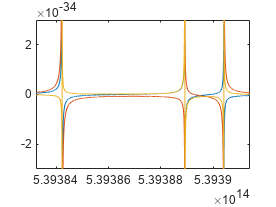

figure;
for rank=0:1:2
plot(light_freq,polarizability(rank+1,:));
hold on
end
ylim([-3e-34,3e-34]);
xlim([min(light_freq) max(light_freq)]);

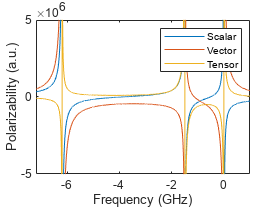



polarizability_inau=polarizability./(4*pi*epsilon0)./(a0^3);
figure;
xaxis=(light_freq-omega_trans(3/2)/2/pi)*1E-9;
for rank=0:1:2
plot(xaxis,polarizability_inau(rank+1,:));
hold on
end
legend("Scalar","Vector","Tensor");
ylabel("Polarizability (a.u.)");
xlabel("Frequency (GHz)");
ylim([-5e6,5e6]);
xlim([min(xaxis) max(xaxis)]);

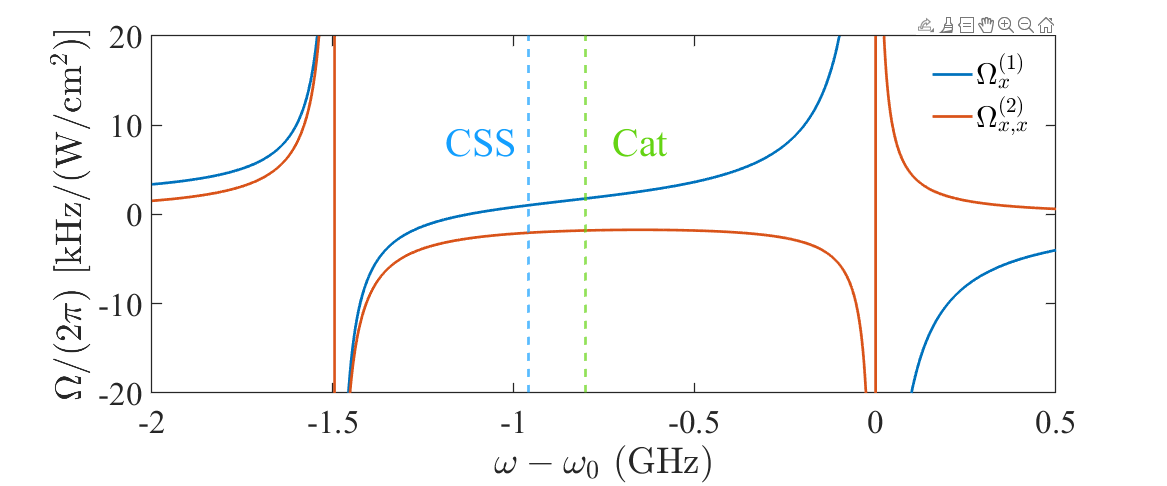

close all;
omega_V=-polarizability(2,:)/(8*5/2)/Constant.Planck/1000*Constant.LightSpeed*Constant.VacuumPermeability*10000;% kHz/(W/cm^2) = Omega/2pi
omega_T=+3/(2*5/2*(2*5/2-1))/4*polarizability(3,:)/Constant.Planck/1000*Constant.LightSpeed*Constant.VacuumPermeability*10000;


figure1=figure;hold on;
l1=plot(xaxis,omega_V);
l2=plot(xaxis,omega_T);
set(l1,'linewidth',2);
set(l2,'linewidth',2);
ylim([-20 20]);
xlim([-2 0.5]);
set(gcf,'Position',[136,339,1167,486],'visible','on')
set(gca,'FontSize',25,'Fontname','Times new roman','box','on','Linewidth',1)
xlabel('$\omega-\omega_0\ \mathrm{(GHz)}$','Interpreter','latex')
ylabel('$\Omega/(2\pi)\ \mathrm{[ kHz/(W/cm^2)]}$','Interpreter','latex')
xline(-0.9599,'--','LineWidth',2,'Color',[0.0745098039215686 0.623529411764706 1]);
xline(-0.800728,'--','LineWidth',2,'Color',[0.392156862745098 0.831372549019608 0.0745098039215686]);
legend('$\Omega_x^{(1)}$','$\Omega_{x,x}^{(2)}$', ...
    'Interpreter','latex','Color','none','EdgeColor','none','location','best')

% 创建 textbox
annotation(figure1,'textbox',...
    [0.375878286270692 0.664359861591696 0.0807916260954238 0.0986159169550171],...
    'Color',[0.0745098039215686 0.623529411764706 1],...
    'String',{'CSS'},...
    'FontSize',30,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

% 创建 textbox
annotation(figure1,'textbox',...
    [0.519013631937685 0.664359861591696 0.0807916260954236 0.0986159169550171],...
    'Color',[0.392156862745098 0.831372549019608 0.0745098039215686],...
    'String','Cat',...
    'FontSize',30,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

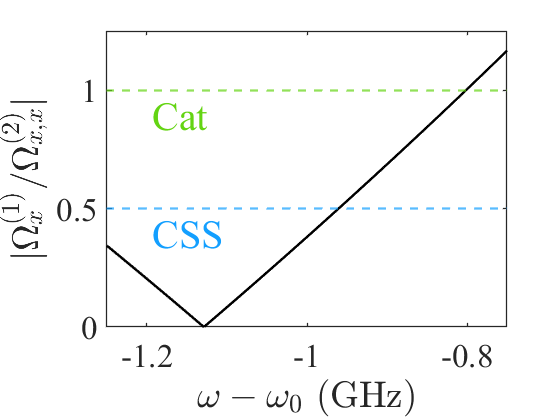



f2 = figure;
l=plot(xaxis,abs(omega_V./omega_T));
xlim([-1.25 -0.75]);
ylim([0 1.25])
set(l,'linewidth',2,'Color','black');
yline(1,'--','LineWidth',1.7,'Color',[0.392156862745098 0.831372549019608 0.0745098039215686]);
yline(0.5,'--','LineWidth',1.7,'Color',[0.0745098039215686 0.623529411764706 1]);
set(gca,'FontSize',25,'Fontname','Times new roman','box','on','Linewidth',1)
xlabel('$\omega-\omega_0\ \mathrm{(GHz)}$','Interpreter','latex')
ylabel('$\vert\Omega_x^{(1)}/\Omega_{x,x}^{(2)}\vert$','Interpreter','latex');

% 创建 textbox
annotation(f2,'textbox',...
    [0.2589 0.6902 0.0808 0.0986],...
    'Color',[0.392156862745098 0.831372549019608 0.0745098039215686],...
    'String','Cat',...
    'FontSize',30,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

% 创建 textbox
annotation(f2,'textbox',...
    [0.2589 0.4096 0.0808 0.0986],...
    'Color',[0.0745098039215686 0.623529411764706 1],...
    'String',{'CSS'},...
    'FontSize',30,...
    'FontName','Times New Roman',...
    'FitBoxToText','off',...
    'EdgeColor','none');

set(gcf,'visible','on');

function polarizability=polar(rank,light_freq)
    polarizability=0;
    a0= 5.2917721067e-11; % Bohr Radius
    hbar=1.05457266*10^-34;
    electron=1.602e-19;
    matrix_element=0.54*a0*electron;
    gamma=2*pi*180e3;
    for F=3/2:1:7/2
        adddition=(-1)^(F+5/2)*(2*F+1)*Wigner6j(1,rank,1,5/2,F,5/2)*(Wigner6j(5/2,1,F,1,5/2,0))^2/hbar*((omega_trans(F)-2*pi*light_freq)/((omega_trans(F)-2*pi*light_freq)^2+gamma^2/4));
        polarizability=polarizability+adddition;        
    end
    polarizability=polarizability*(-1)^(rank+1)*(5/2*2+1)*sqrt(2*rank+1)*matrix_element^2;
    if rank==0
        polarizability=polarizability/(sqrt(3*(2*5/2+1)));
    elseif rank==1
        polarizability=-polarizability*sqrt(2*5/2/((5/2+1)*(2*5/2+1)));
    elseif rank==2
        polarizability=-polarizability*sqrt((2*5/2*(2*5/2-1))/(3*(5/2+1)*(2*5/2+1)*(2*5/2+3)));
    end
end
%%
function omega=omega_trans(F)
    ref_freq=539390406.83*10^6;        % 171:1/2-3/2
    ref_freq0=ref_freq-4759.440*10^6;   % 176
    if F==5/2
        omega=ref_freq0+3266.243*10^6;
        
    elseif F==7/2
        omega=ref_freq0-1431.872*10^6;
    elseif F==3/2
        omega=ref_freq0+4762.110*10^6;
    else
        disp("Wrong input");
        omega=0;
    end
    omega=omega*2*pi;
end